clear all
H = [4 -4; -4 3]

H =      4    -4
    -4     3


eig(H)

ans =    -0.5311
    7.5311



syms dx1 dx2 x1 x2 u

4*u^2-8*u+3 == 0

$$ans = 4\,u^{2}-8\,u+3=0$$

var = vpasolve(ans,u)

$$var = \left(\begin{array}{c} 0.5\\ 1.5 \end{array}\right)$$

f = 2*x1^2 - 4*x1*x2 + 1.5*x2^2 + x2 

$$f = 2\,{x_{1}}^{2}-4\,x_{1}\,x_{2}+\frac{3\,{x_{2}}^{2}}{2}+x_{2}$$

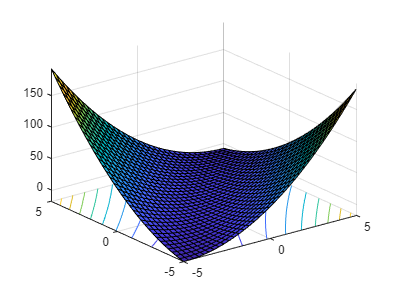

fsurf(f,'ShowContours','on')

g = gradient(f)

$$g = \left(\begin{array}{c} 4\,x_{1}-4\,x_{2}\\ 3\,x_{2}-4\,x_{1}+1 \end{array}\right)$$

x1 = 1; x2 = 1;
dx = [dx1;dx2];
H = hessian(f)

$$H = \left(\begin{array}{cc} 4 & -4\\ -4 & 3 \end{array}\right)$$

eig(H)

$$ans = \left(\begin{array}{c} \frac{7}{2}-\frac{\sqrt{65}}{2}\\ \frac{\sqrt{65}}{2}+\frac{7}{2} \end{array}\right)$$

eigH = double(eig(H))

eigH =    -0.5311
    7.5311


[dx1;dx2]'*H*[dx1;dx2]

$$ans = {\mathrm{dx}}_{1}\,\left(4\,\bar{{\mathrm{dx}}_{1}}-4\,\bar{{\mathrm{dx}}_{2}}\right)-{\mathrm{dx}}_{2}\,\left(4\,\bar{{\mathrm{dx}}_{1}}-3\,\bar{{\mathrm{dx}}_{2}}\right)$$

% Compute analytic solution of a symbolic equation
solution = solve(ans,[dx1,dx2]);
% Display symbolic solution returned by solve
displaySymSolution(solution);

solution = struct with fields:
    dx1: 0
    dx2: 0


where


$$\left(\begin{array}{cc} {\mathrm{dx}}_{1} & {\mathrm{dx}}_{2} \end{array}\right)=\left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

## problem 2


a = [1:3]';
x = sym("x",[3 1]);
xe = [-1 0 1]';
x0 = [100 50 10]';
f = (-2*x(2)-3*x(3)+2)^2 +x(2)^2+(x(3)-1)^2

$$f = {\left(x_{3}-1\right)}^{2}+{\left(2\,x_{2}+3\,x_{3}-2\right)}^{2}+{x_{2}}^{2}$$

g = gradient(f);
h = jacobian(g,x(2:3));
z = [1;2];
z'*h*z

$$ans = 138$$

lambda = double(eig(h))

lambda =      2
    28


syms l 
56-30*l+l^2

$$ans = l^{2}-30\,l+56$$



% t = 0.5; alpha = 1;
% phi = subs(f,x,x0) - t*g'*g*alpha
% counter = 1;
% ff = subs(f,x,x0-alpha*g)
% while subs(f,x,x0-alpha*g) > phi && counter <= 100
%     alpha = alpha*0.5
%     phi = subs(f,x,x0) - t*g'*g*alpha
%     counter = counter +1
% end

% fh = matlabFunction(f,g,h,'vars',{x});
% options = optimoptions('fminunc', ...
%     'SpecifyObjectiveGradient', true, ...
%     'HessianFcn', 'objective', ...
%     'Algorithm','quasi-newton', ...
%     'Display','final');
% [xfinal,fval,exitflag,output] = fminunc(fh,[0;0;0],options)
